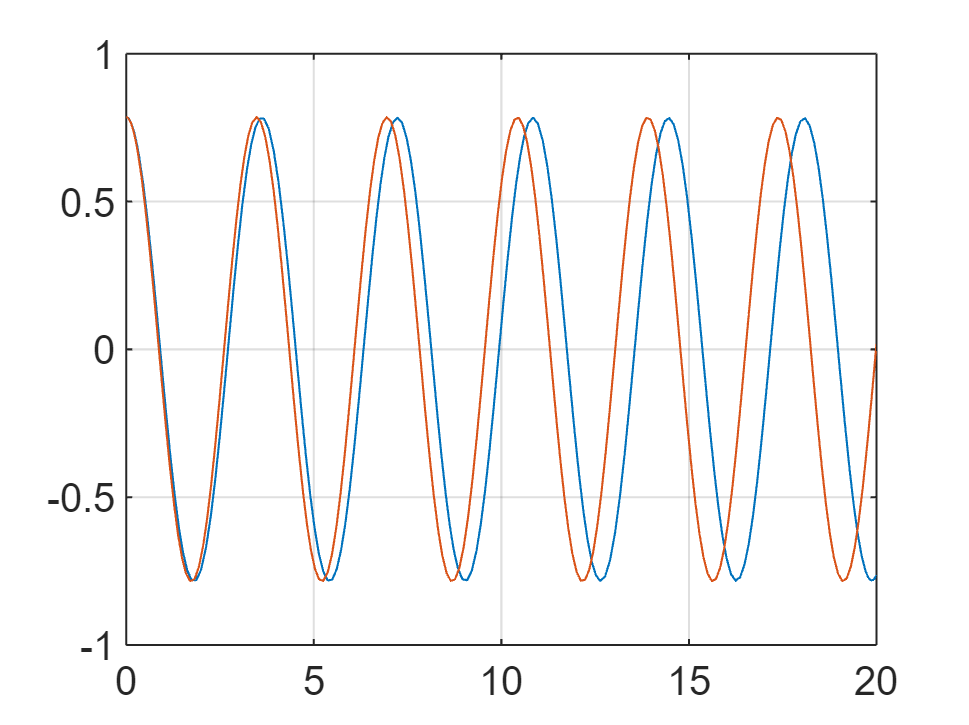

close all
clear all
l = 3; % Länge des Fadens in m
r = 0.1; % Radius der Kugel in m
phi0 = pi/4;
beobd = 20;

[t,u] = ode45(@pendel, [0 beobd], [phi0 0]);
[t_n,u_n] = ode45(@pendel_kleine_a, [0 beobd], [phi0 0]);

plot(t,u(:,1))
hold on
plot(t_n, u_n(:,1))
grid on
hold off

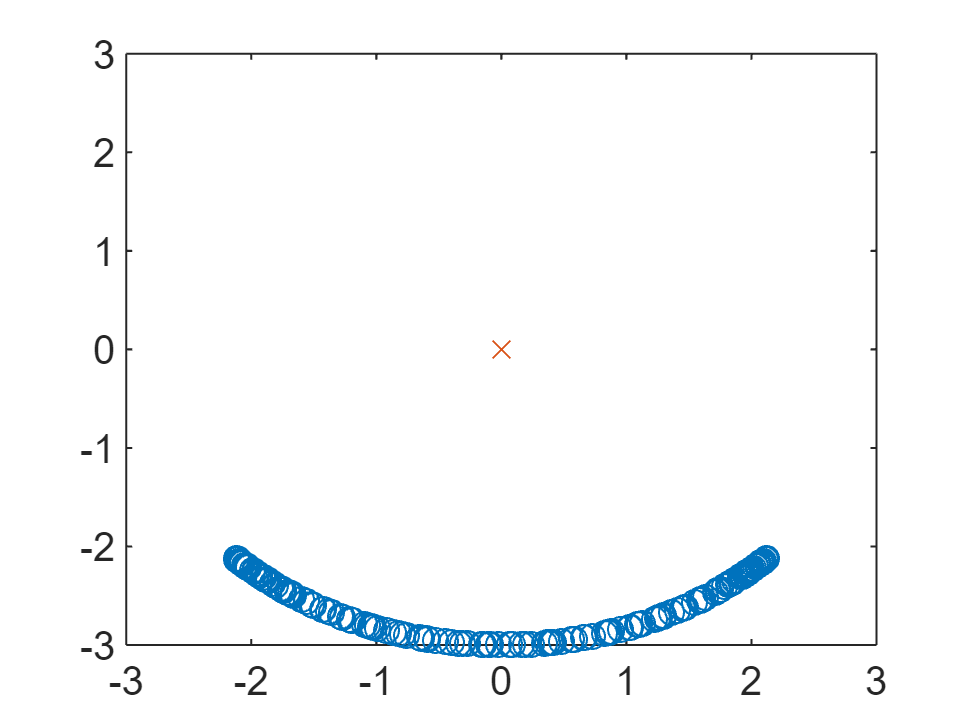


xkor = l * sin(u(:,1));
ykor = -l * cos(u(:,1));

plot(xkor, ykor, 'o')
hold on
plot(0,0,'x')
axis([-l l -l l])
hold off

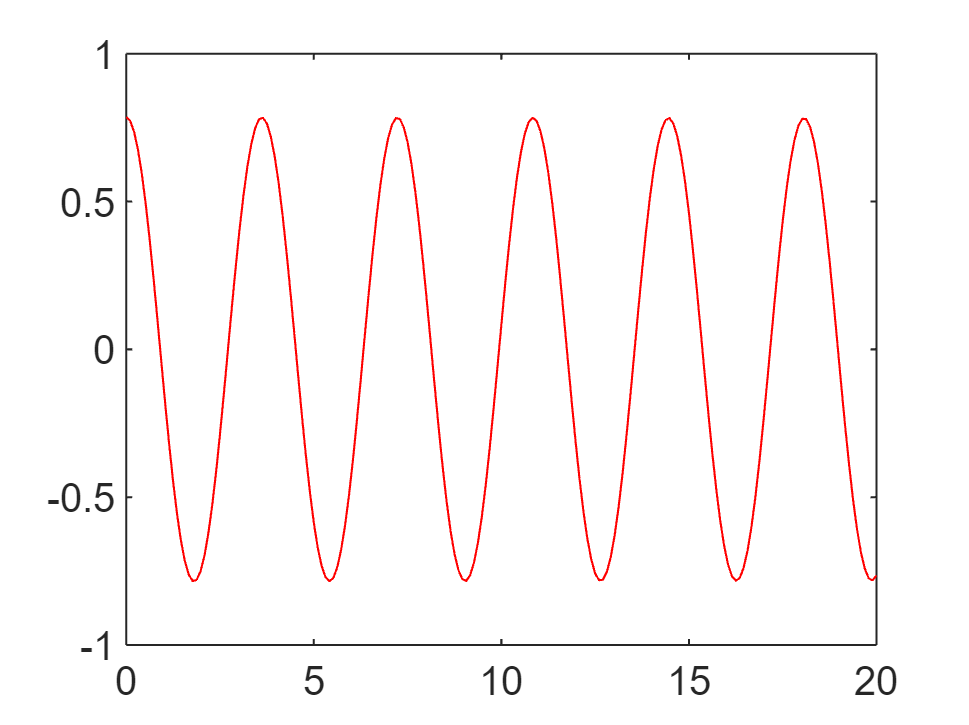


% Spline interpolation for evenly distr. time
t_new = linspace(0,t(end),length(t));
phi_new = interp1(t, u(:,1), t_new, 'spline');
plot(t_new,phi_new,'r')

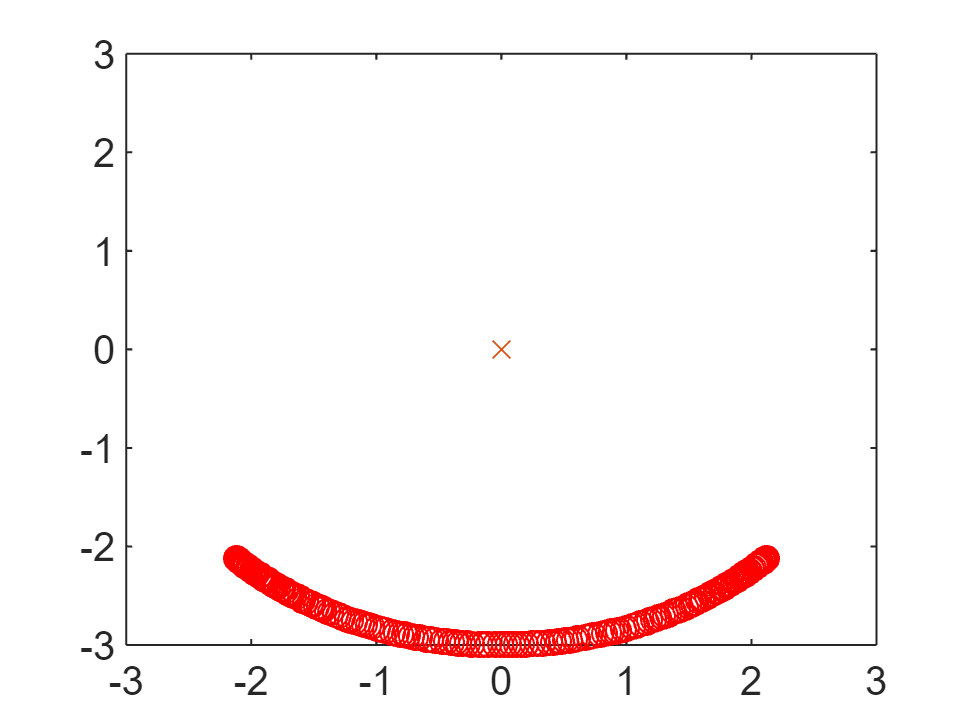


xkor_new = l * sin(phi_new);
ykor_new = -l * cos(phi_new);
plot(xkor_new, ykor_new, 'ro')
hold on
plot(0,0,'x')
axis([-l l -l l])


% Exporting to .csv
data = [l*ones(size(t)), r*ones(size(t)), xkor, ykor];
writematrix(data, 'coordinates.csv')